##  МИУ

комбинированный МИУ для диэл цилиндра

19.04.21

close all;
clear variables;

Входные параметры

%  1 - входные данные 
k0 = 2*pi;
% Параметры среды-1
e1 = 2.56;
mu1 = 1;
k1 = k0*sqrt(mu1*e1);
eta1 = 120*pi*sqrt(mu1/e1);

% Параметры среды-2
k2 = k0;
eta2 = 120*pi;

% Параметры программы
a = 5/(2*pi);  % радиус круга
N = 100; % количество точек на круга
phi_i_grad = 0; % угол падения [град]
phi_i_rad = 2*pi/360*phi_i_grad; % угол падения [рад]
gamma = 1.781072417990;

% ========================================================================
%  Построение круга
dphi_grad = 360/N; % угловой шаг на круга [град]
dphi_rad =  2*pi/360*dphi_grad; % угловой шаг на круга [рад]
dx = 2*a*sin(dphi_rad/2);
dx2 = dx/2; 

% круга в полярной системе координат (пусть будет)
% получение векторов углов и вектора ридиусов
phi_circl_rad = zeros(1, N);
phi_circl_grad = zeros(1, N);
a_for_graph = zeros(1, N);
for i = 1 : N
    phi_circl_rad(i) = (i-1)*dphi_rad + dphi_rad/2;
    phi_circl_grad(i) = (i-1)*dphi_grad + dphi_grad/2;
    a_for_graph(i) = a;
end

Генерация точек

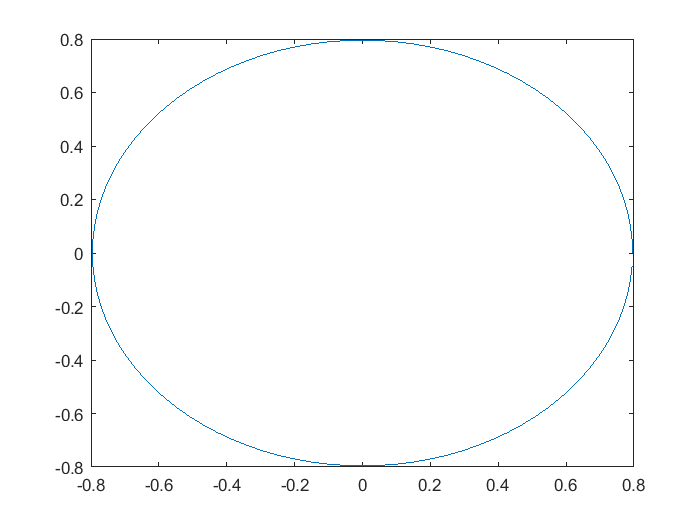

dphi_grad = 360/N;
x = zeros(1,N);
z = zeros(1,N);

for i = 1 : N
    z(i) = a*sind(dphi_grad*(i-1));
    x(i) = a*cosd(dphi_grad*(i-1));
end

plot(x,z)

Посчитаем t для каждого отрезка

for i = 1 : N
    if i == N
        tx(i) = -((x(1)-x(i)))/dx;
        tz(i) = -((z(1)-z(i)))/dx;
    else
        tx(i) = -(x(i+1)-x(i))/dx;
        tz(i) = -(z(i+1)-z(i))/dx;
    end
end

Посчитаем n для каждого отрезка

%  Посчитаем n для каждого отрезка
%  нормальный вектор найдем с помощью матрицы повороты
    alpha = -90;
    matrix = [cosd(alpha),-sind(alpha); sind(alpha),cosd(alpha)];

for i = 1 : N
     matrix_temp = [tx(i), tz(i)]*matrix;
     nx(i) = matrix_temp(1);
     nz(i) = matrix_temp(2);
end

Координаты центров отрезков

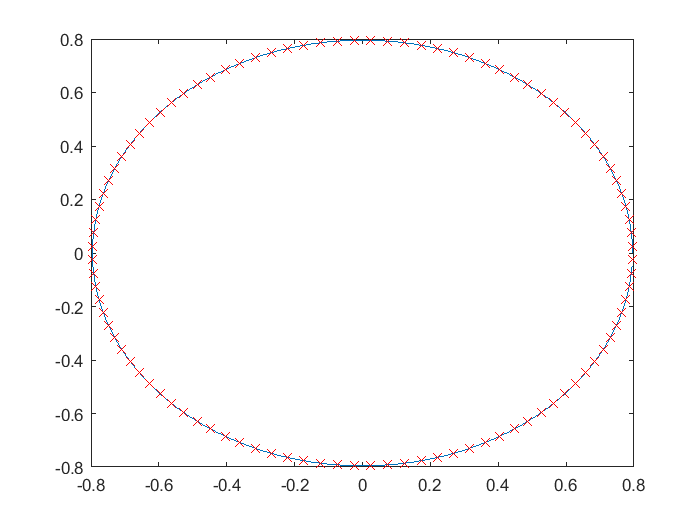

for i = 1 : N 
    if i == N
        x_midle(i) = ((x(1)+x(i)))/2;
        z_midle(i) = ((z(1)+z(i)))/2;
    else
        x_midle(i) = (x(i+1)+x(i))/2;
        z_midle(i) = (z(i+1)+z(i))/2;
    end    
end

plot(x,z,x_midle, z_midle, 'rx');

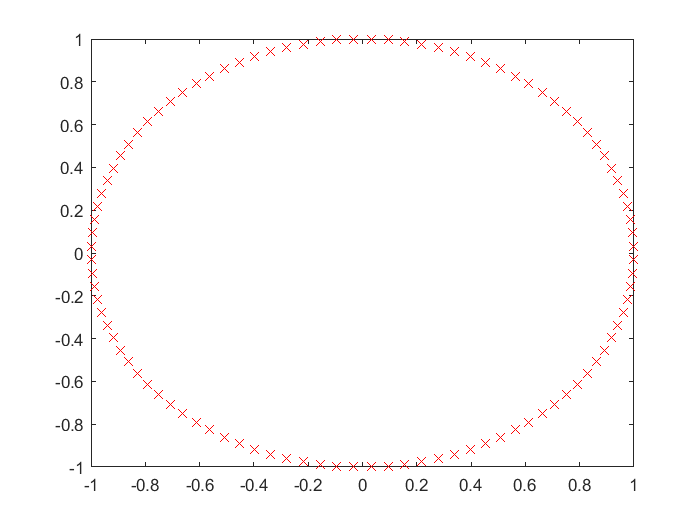


% визуализируем tx и tz
plot(tx, tz, 'rx');

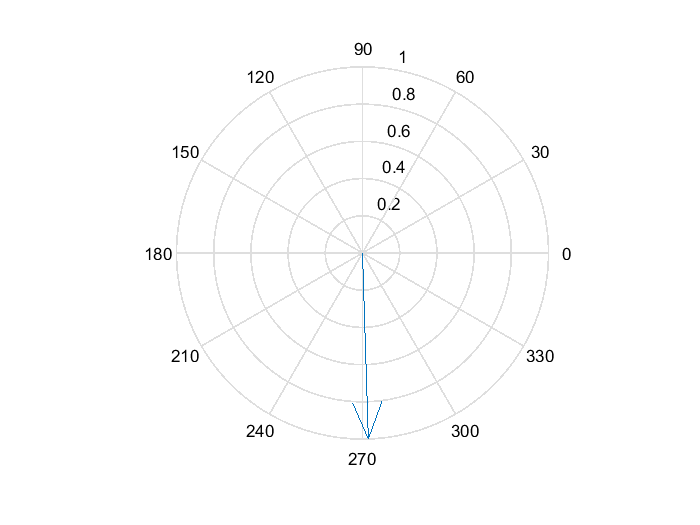

compass(tx(1),tz(1));


% ========================================================================
% 3 - cам ходя расчета 
% списик для хранения элементов системы 
Z = zeros(2*N,2*N);
Y = zeros(2*N,2*N);
    
for m  = 1 : N
    xm = x_midle(m);
    zm = z_midle(m);
    txm = tx(m);
    tzm = tz(m);
    nxm = nx(m);
    nzm = nz(m);
    
    for n = 1 : N
        xn = x_midle(n);
        zn = z_midle(n);
        txn = tx(n);
        tzn = tz(n);
        nxn = nx(n);
        nzn = nz(n);
            
        % Растояние между началом координат О2 и точкой наблюдений (в ГСК)        
        x_mO2 = xm - xn;
        z_mO2 = zm - zn;
        
        % Положим этот вектор на новую СК
        % Координаты этой точки (в ЛСК)
        umn = x_mO2*txn + z_mO2*tzn;
        wmn = x_mO2*nxn + z_mO2*nzn;
        
        
        % локальные замены 
        xmn = xm - xn;
        zmn = zm - zn;
        r = sqrt(xmn^2 + zmn^2);
        
        umn_plus = umn + dx/2;
        umn_minus = umn - dx/2; 
        r_minus = sqrt(umn_minus^2 + wmn^2);
        r_plus = sqrt(umn_plus^2 + wmn^2);
        rmn = sqrt(umn^2 + wmn^2);
        
        if n == m
          % электрическое поле
            % cоставляющие E1y
            fe_y1 = 1i/4*dx*(1 + 1i*2/pi*(log(gamma*k1*dx/4)-1));
            fm_y1 = +1/2;
            
            % cоставляющие E2y
            fe_y2 = 1i/4*dx*(1 + 1i*2/pi*(log(gamma*k2*dx/4)-1));
            fm_y2 = -1/2;

          % магнитное поле
            % cоставляющие H1u
            hm_u11 = 0;
            hm_u12 = fe_y1;
            he_u1 = fm_y1;
 
            % cоставляющие H2u
            hm_u21 = 0;
            hm_u22 = fe_y2;
            he_u2 = fm_y2;

            % cоставляющие H1w
            hm_w1 = 0;
            he_w1 = 0;
 
            % cоставляющие H2w
            hm_w2 = 0;
            he_w2 = 0;

        elseif abs(n-m) <= -1.5
        
          % электрчиеское поле
            % cоставляющие E1y
            fe_y1 = dx + 2*1i/pi * (wmn*(atan(umn_plus/wmn) - atan(umn_minus/wmn))...
            + umn_plus*log(gamma*k1/2*sqrt(umn_plus^2+wmn^2))...
            - umn_minus*log(gamma*k1/2*sqrt(umn_minus^2+wmn^2)) - dx);
            fe_y1 = fe_y1 * i/4;
            
            fm_y1 = -1i/8*wmn*k1^2*dx - 1/(2*pi)*(atan(umn_plus/wmn) - atan(umn_minus/wmn));
            
            % cоставляющие E2y
            fe_y2 = dx + 2*1i/pi * (wmn*(atan(umn_plus/wmn) - atan(umn_minus/wmn))...
            + umn_plus*log(gamma*k2/2*sqrt(umn_plus^2+wmn^2))...
            - umn_minus*log(gamma*k2/2*sqrt(umn_minus^2+wmn^2)) - dx);
            fe_y2 = -fe_y2 * i/4;
            
            fm_y2 = -1i/8*wmn*k2^2*dx - 1/(2*pi)*(atan(umn_plus/wmn) - atan(umn_minus/wmn));
            
          % магнитное поле
            % cоставляющие H1u
            hm_u11 = - 1i/4*k1*(umn_plus/r_plus*H(0,k1*r_plus) - umn_minus/r_minus*H(0,k1*r_minus));
            hm_u12 = fe_y1;
            he_u1 = fm_y1;

            % cоставляющие H2u
            hm_u21 = - 1i/4*k2*(umn_plus/r_plus*H(0,k2*r_plus) - umn_minus/r_minus*H(0,k2*r_minus));
            hm_u22 = fe_y2;
            he_u2 = fm_y2;

            % cоставляющие H1w
            hm_w1 = - 1i/4*k1*(wmn/r_plus*H(1,k1*r_plus) - wmn/r_minus*H(1,k1*r_minus));
            he_w1 = + 1i/4*(H(0,k1*r_plus) - H(0,k1*r_minus));

            % cоставляющие H2w
            hm_w2 = - 1i/4*k2*(wmn/r_plus*H(1,k2*r_plus) - wmn/r_minus*H(1,k2*r_minus));
            he_w2 = + 1i/4*(H(0,k2*r_plus) - H(0,k2*r_minus));
        else
          % электрчиеское поле
            % cоставляющие E1y
            fe_y1 = 1i/4*dx*H(0,k1*rmn);
            fm_y1 = - 1i/4*k1*dx*(wmn/rmn*H(1,k1*rmn));
            
            % cоставляющие E2y
            fe_y2 = 1i/4*dx*H(0,k2*rmn);
            fm_y2 = - 1i/4*k2*dx*(wmn/rmn*H(1,k2*rmn));
            
          % магнитное поле
            % cоставляющие H1u
            hm_u11 = - 1i/4*k1*(umn_plus/r_plus*H(0,k1*r_plus) - umn_minus/r_minus*H(0,k1*r_minus));
            hm_u12 = fe_y1;
            he_u1 = fm_y1;
            
            % cоставляющие H2u
            hm_u21 = - 1i/4*k2*(umn_plus/r_plus*H(0,k2*r_plus) - umn_minus/r_minus*H(0,k2*r_minus));
            hm_u22 = fe_y2;
            he_u2 = fm_y2;
            
            % cоставляющие H1w
            hm_w1 = - 1i/4*k1*(wmn/r_plus*H(1,k1*r_plus) - wmn/r_minus*H(1,k1*r_minus));
            he_w1 = + 1i/4*(H(0,k1*r_plus) - H(0,k1*r_minus));
            
            % cоставляющие H2w
            hm_w2 = - 1i/4*k2*(wmn/r_plus*H(1,k2*r_plus) - wmn/r_minus*H(1,k2*r_minus));
            he_w2 = + 1i/4*(H(0,k2*r_plus) - H(0,k2*r_minus));
            
        end
        % элементы системы       
        % cоставляющие E1y
        E1y = 1i*eta1*k1*fe_y1 + fm_y1;
        
        % cоставляющие E2y
        E2y = 1i*eta2*k2*fe_y2 - fm_y2;
        
        % cоставляющие H1u
        H1u = 1i/(eta1*k1)*(hm_u11 + k1^2*hm_u12) - he_u1;
        
        % cоставляющие H2u
        H2u = -1i/(eta2*k2)*(hm_u21 + k2^2*hm_u22) - he_u2;
        
        % cоставляющие H1w
        H1w = 1i/(eta1*k1)*hm_w1 + he_w1;
        
        % cоставляющие H2w
        H2w = -1i/(eta2*k2)*hm_w2 + he_w2;
        
        % засунем в систему для расчета
        E1mn = E1y;
        E2mn = -E2y;
        
        dot_tm_tn = (txm*txn+tzm*tzn);
        dot_tm_nn = (txm*nxn+tzm*nzn);
        
        H1mn = dot_tm_tn*H1u + dot_tm_nn*H1w;
        H2mn = -(dot_tm_tn*H2u + dot_tm_nn*H2w);
        
        % запись в массив для дальнешего решения 
        Z(m,n) = E1mn;
        Z(m,n+N) = E2mn;
        Z(m+N,n) = H1mn;
        Z(m+N,n+N) = H2mn;
    end
end

E = zeros(2*N,1);
% падающее поле 
for m = 1 : N
    xm = x_midle(m);
    zm = z_midle(m);
    txm = tx(m);
    tzm = tz(m);

    % cоставляющие полей
    cx = -1i*k2*cosd(phi_i_grad);
    cz = -1i*k2*sind(phi_i_grad);
    
    Eiy = exp(cx*xm+cz*zm);
    Hix = 1/eta2*sind(phi_i_grad) * Eiy;
    Hiz = -1/eta2*cosd(phi_i_grad) * Eiy;
    
    % элементы системы  
    Ei = Eiy;
    Hi = txm*Hix + tzm*Hiz;

    % запись в массив для дальнешего решения 
    E(m) = Ei;
    E(m+N) = Hi;
end    

% Расчитаем токи
% тут зашито сразу 2 тока
I = Z\E;

% отделим один ток от другого
j1 = I(1:N);
j2 = I(N+1:2*N);

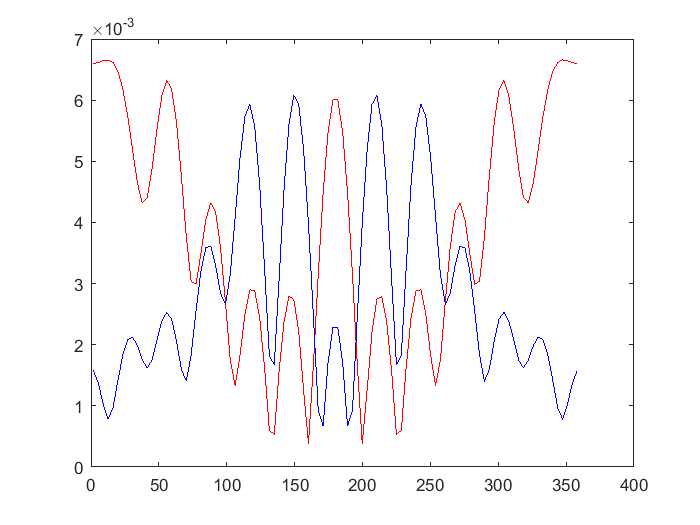

% построим эти графики 
plot(phi_circl_grad,  abs(j1), 'r',phi_circl_grad, abs(j2), 'b');

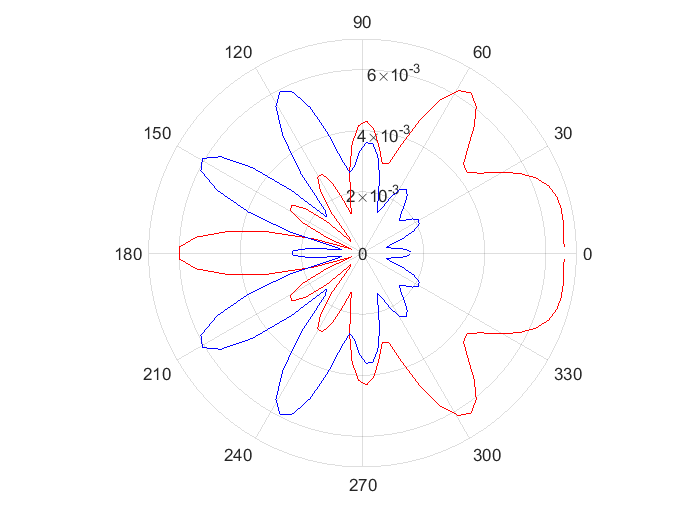


% полярный графки токов
polarplot(phi_circl_rad, abs(j1), 'r',phi_circl_rad, abs(j2), 'b');

## ЭПР

for p = 1 : 721
    Sum_E = 0;
    phi = (p-1)/2; % угол из формулы для приведения 721 к 360 градусам
    phi_for_graf_DA(p) = (p-1)/2; % угол для графика
    
    cx = - 1i*k2*cosd(phi);
    cz = - 1i*k2*sind(phi);
    

        for n = 1 : N
            txn = tx(n);
            tzn = tz(n);
            xn = x_midle(n);
            zn = z_midle(n);
            
            Sum_E = Sum_E + eta2*k2/4*dx*j2(n)*exp(cx*xn+cz*zn);      
        end
    
    RCS(p) = 10*log10((4/k2)*Sum_E*conj(Sum_E));
    RCS_norm(p) = 10*log10((4/(k2*pi*a))*Sum_E*conj(Sum_E));
end


% график поля в дальней зоне от угла налюденя (не нормированный)
figure;
plot(phi_for_graf_DA, RCS,'r-');

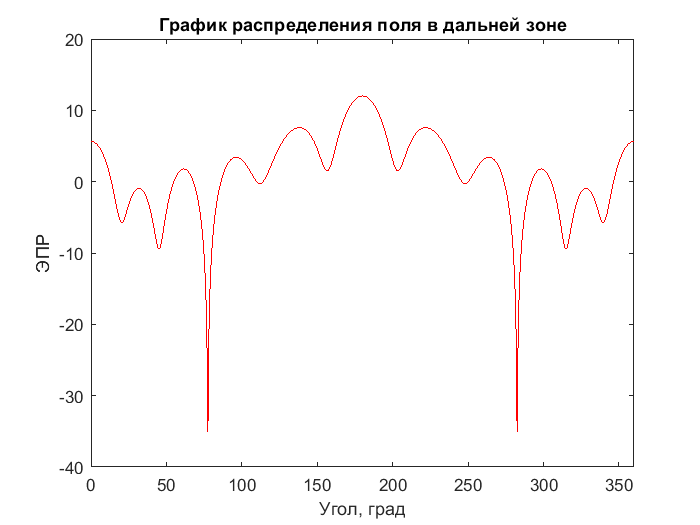

title('График распределения поля в дальней зоне'); 
xlim([0 360])
xlabel('Угол, град'); 
ylabel('ЭПР');

### Вывод данных для графиков

% name_file = strcat('I_MIE_circl_diel_Epol_j1_', num2str(N),'.dat');
% f01 = fopen(name_file,'w');
% 
% % за максимум Y примем значения в центре передней стороны падения
% 
% for n=1:N
%     fprintf(f01,' %10.5f %10.5f\n', phi_circl_grad(n), abs(j1(n)));
% end
% 
% fclose(f01);

% name_file = strcat('I_MIE_circl_diel_Epol_j2_', num2str(N),'.dat');
% f02 = fopen(name_file,'w');
% 
% % за максимум Y примем значения в центре передней стороны падения
% 
% for n=1:N
%     fprintf(f02,' %10.5f %10.5f\n', phi_circl_grad(n), abs(j2(n)));
% end
% 
% fclose(f02);

% name_file = strcat('DA_MIE_circl_diel_Epol_j2_', num2str(N),'.dat');
% f03 = fopen(name_file,'w');
% 
% % за максимум Y примем значения в центре передней стороны падения
% 
% for n= 1 : 721
%     fprintf(f03,' %10.5f %10.5f\n', phi_for_graf_DA(n), RCS(n));
% end
% 
% fclose(f03);

function [H_calc] = H(n,x)
    H_calc = besselh(n,1,x); 
end

function [J_calc] = J(n,x)
    J_calc = besselJ(n,x); 
end
    
function [dJ_calc] = dJ(n,x)
    dJ_calc = n/x*besselj(n,x) - besselj(n+1,x);
end

function [dH_calc] = dH(n,x)
    dH_calc = n/x*besselh(n,1,x) - besselh(n+1,1,x);
end